### Circuito Linea de Tranmision

clear all
Start_Freq=0.1E9;
End_Freq=2E9;
Step=1000;
Z0=50;

netlist_TLfile='NetlistSpice\1_Circuito_Extra_ABCD.net';
netlistCell=Netlist2CellArray(netlist_TLfile)

netlistCell = 12×7 cell array
    {'R1' }    {'N003'}    {'N006'}    {'R' }    {[        75]}    {[ 0]}    {[         0]}
    {'R2' }    {'N005'}    {'N007'}    {'R' }    {[        75]}    {[ 0]}    {[         0]}
    {'C2' }    {'N003'}    {'N010'}    {'C' }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C1' }    {'N009'}    {'N003'}    {'C' }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C3' }    {'N010'}    {'N005'}    {'C' }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C4' }    {'N005'}    {'N002'}    {'C' }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'R4' }    {'N007'}    {'0'   }    {'R' }    {[        75]}    {[ 0]}    {[         0]}
    {'R5' }    {'N003'}    {'N008'}    {'R' }    {[        75]}    {[ 0]}    {[         0]}
    {'TL1'}    {'N006'}    {'0'   }    {'TL'}    {[        45]}    {[45]}    {[1.0000e+09]}
    {'R3' }    {'N004'}    {'N005'}    {'R' }    {[        75]}    {[ 0]}    {[         0]}
    {'R6' }    {'N009'}    {'N001'}    {'R' }    {


% Metodo Objeto Circuito Matlab
SMatlab4=SParametersFromNetlist(netlistCell,Start_Freq,End_Freq,Step,Z0);

TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 60
            LineLength: 1.0472
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


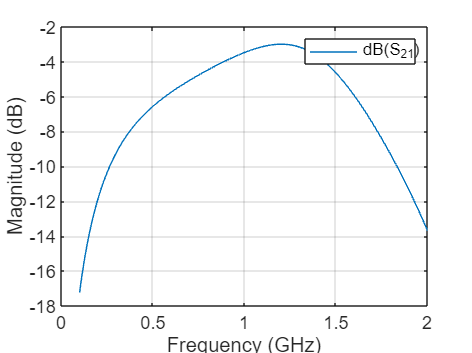

rfplot(SMatlab4);


% Metodo circuito equivalente
nuevo_Netlist=NetlistCircuitoEquivalente(netlistCell)

nuevo_Netlist = 16×7 cell array
    {'R1'   }    {'N003'}    {'N006'}    {'R'    }    {[        75]}    {[     0]}    {[         0]}
    {'R2'   }    {'N005'}    {'N007'}    {'R'    }    {[        75]}    {[     0]}    {[         0]}
    {'C2'   }    {'N003'}    {'N010'}    {'C'    }    {[1.2000e-11]}    {[     0]}    {[         0]}
    {'C1'   }    {'N009'}    {'N003'}    {'C'    }    {[1.2000e-11]}    {[     0]}    {[         0]}
    {'C3'   }    {'N010'}    {'N005'}    {'C'    }    {[1.2000e-11]}    {[     0]}    {[         0]}
    {'C4'   }    {'N005'}    {'N002'}    {'C'    }    {[1.2000e-11]}    {[     0]}    {[         0]}
    {'R4'   }    {'N007'}    {'0'   }    {'R'    }    {[        75]}    {[     0]}    {[         0]}
    {'R5'   }    {'N003'}    {'N008'}    {'R'    }    {[        75]}    {[     0]}    {[         0]}
    {'R3'   }    {'N004'}    {'N005'}    {'R'    }    {[        75]}    {[     0]}    {[         0]}
    {'R6'   }    {'N009'}    {'N001'}    {'R'    }    {[   

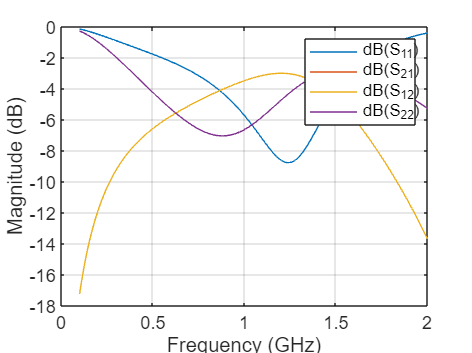

Matriz_Z=Z_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);
Matriz_S=z2s(Matriz_Z,50);

freq=linspace(Start_Freq, End_Freq, Step);
SParamsObject=sparameters(Matriz_S,freq,50);
rfplot(SParamsObject)


% ----- INICIO----------


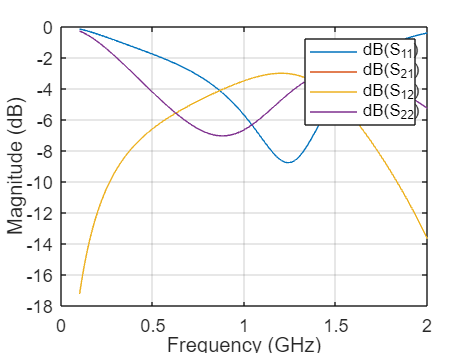

rfplot(SParamsObject,2,1)

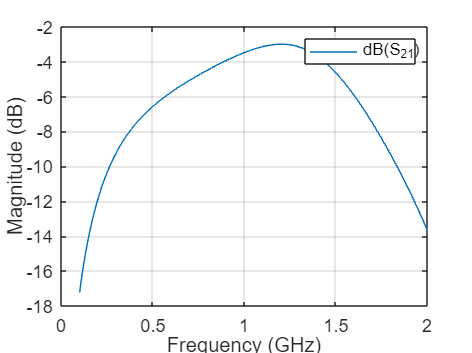

rfplot(SMatlab4,2,1)